## Informação dos picos

% N170 (100-200 ms) - Potencial com amplitude maior durante a apresenção de faces em
% comparação com outros objetos/estímulos visuais. Elétrodos: P7, P8, PO7, PO8.
% Geralmente é mais pronunciando no hemisfério direito.
% Vertex Positive Potential (VPP) - 100 - 200 ms. Parece ser gerado pelo mesmo 
% processo neuronal de reconhecimento facil mas é captado nos elétrodos centrais: 
% FZ, CZ, apesar do poder haver pequenas diferenças de latência.
% Mais sobre o N170 e VPP: https://psyc.bbk.ac.uk/brainb/wp-content/uploads/sites/13/2019/05/eimer_N170_oxford.pdf

% N2 (200-400 ms): FZ, Cz, PO7, PO8
% P3 (300-600 ms): FZ, Fz, Pz
% https://onlinelibrary.wiley.com/doi/pdfdirect/10.1111/j.1469-8986.2007.00602.x

## Importar os dados e inicializar variáveis

close all;
clc, clear;

fig = 1;

% EEGLAB functions documentation: https://sccn.ucsd.edu/~arno/eeglab/auto/indexfunc.html

addpath(genpath('eeglab2023.0')); % Path do EEGLAB 
ch_locs=readlocs('BioSemi64.loc'); % Ficheiro com localização dos elétrodos

readlocs(): 'loc' format assumed from file extension



data_seated = readtable("S3_25_Male.csv");
data_seated = table2array(data_seated);

fs = 125;
channel_labels = ["C3";"CP3";"P3";"P7";"PO7";"PO3";"Pz";"CPz";"Fz";"Cz";"C4";"CP4";"P4";"P8";"PO8";"PO4"];

idx = zeros(length(channel_labels),1);

for i = 1:length(ch_locs)
    cur_lb = string(ch_locs(i).labels);
    if (nonzeros(channel_labels == cur_lb))
        idx(i) = 1;
    end
end

nch_locs = ch_locs(logical(idx)); % Elétrodos usados

nch_locs

nch_locs = 1×16 struct array with fields:
    theta
    radius
    labels
    sph_theta
    sph_phi
    sph_radius
    sph_theta_besa
    sph_phi_besa
    X
    Y
    Z


## 2D plot

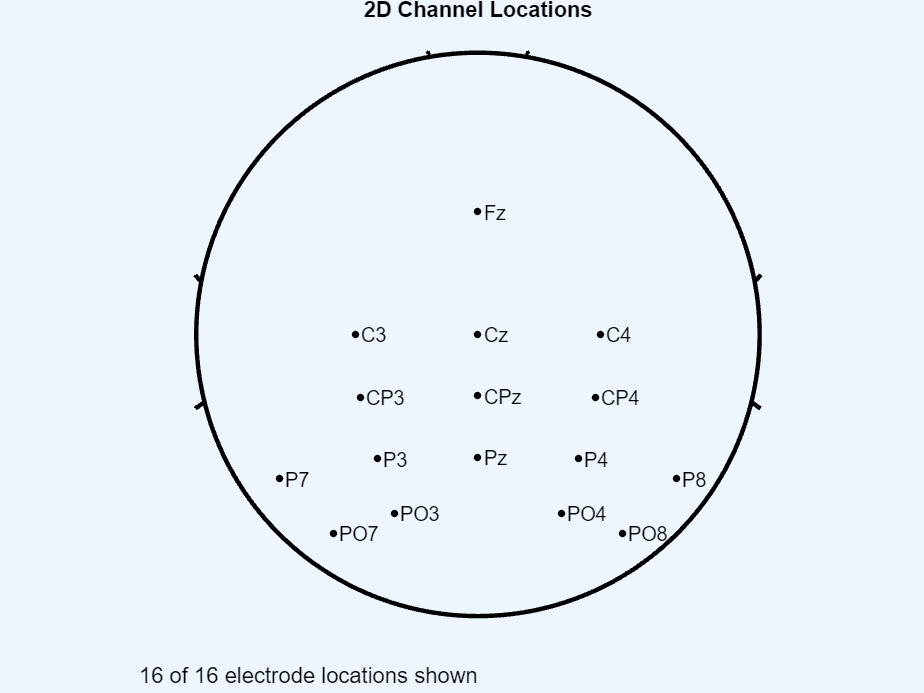

figure (fig), topoplot([], nch_locs, 'style', 'blank', 'electrodes', 'ptslabels');
fig = fig + 1;
title(["2D Channel Locations";""]);

## Headplot

Headplot: using existing XYZ coordinates
Loaded mesh file mheadnew.mat
Setting up splining matrix.
Calculating splining matrix...
Computing electrode locations on head...
Computing 6067 vertices. Should take a while (see wait bar)
            but does not have to be done again for this montage...
Saving (780k) file FileHeadPlot.spl


splfile='FileHeadPlot.spl';
headplot('setup',nch_locs,splfile,'Param','Value');

Loaded mesh file mheadnew.mat


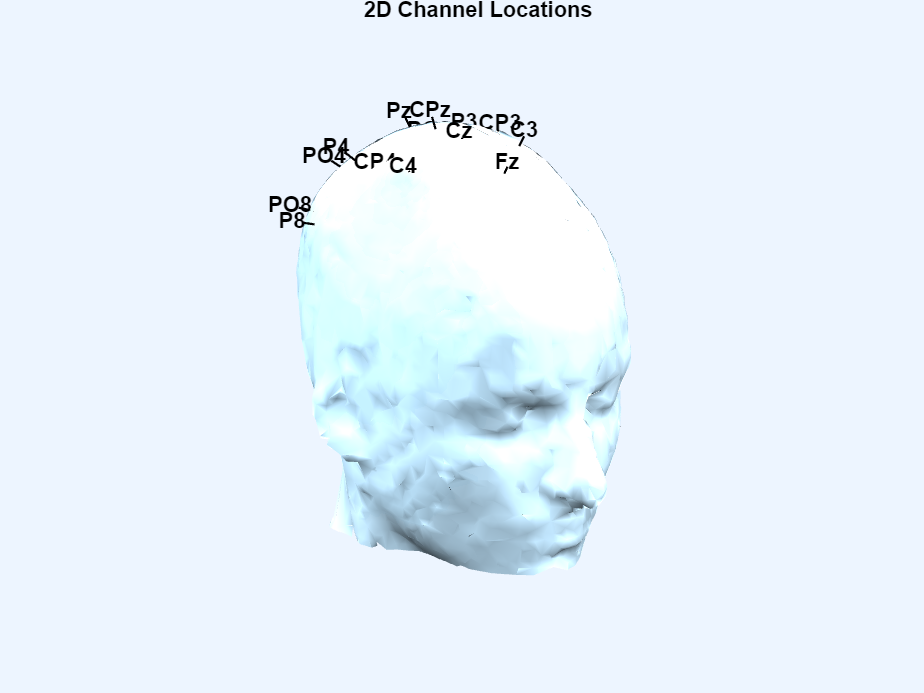

headplot(data_seated(100000,1:(end-1)),splfile,'electrodes','on','labels',2,'maplimits', 'absmax','colormap', sky(64));

## Verificar o efeito dos filtros na fase dos sinais

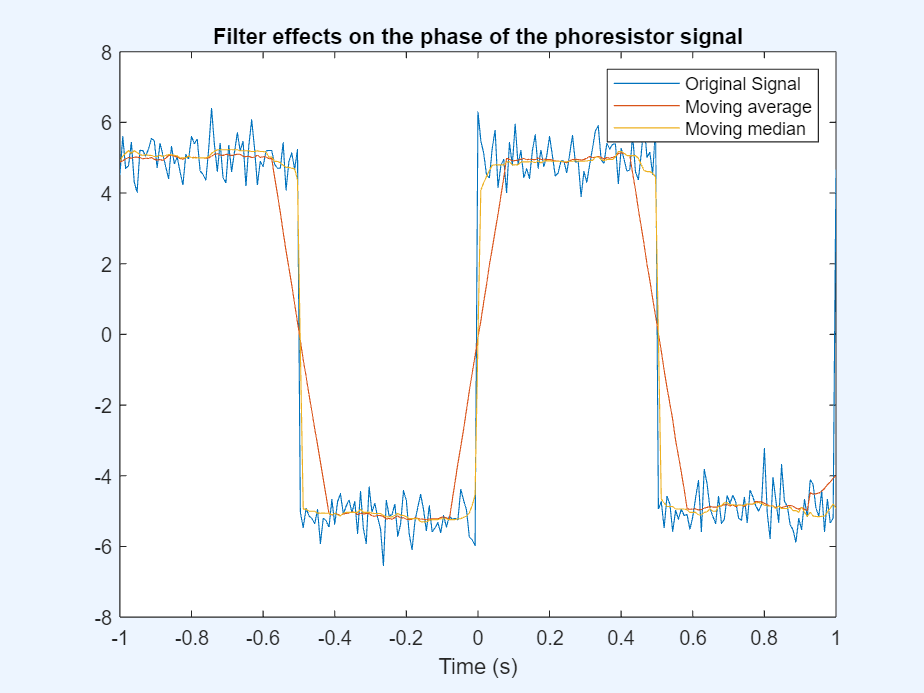

t = (-1:1/fs:1)';
s = 5*square(2*pi*t); % Sinal com a mesma frequência que o sinal da fotoresistência

sqwave = awgn(s, 20, 'measured'); % Whiete noise gaussiano

plot(t, [sqwave, movmean(sqwave,20), movmedian(sqwave,20)]),
title('Filter effects on the phase of the phoresistor signal'), 
xlabel('Time (s)'),
legend('Original Signal','Moving average','Moving median');

% Resumindo, a mediana flutuante não distorce tanto as fases do sinal,
% principalmente no início das rising edges e falling edges. Isto é
% extremamente importante em análises como as dos ERPs pois é preciso
% saber com exatidão o instante em que o estímulo é apresentado.

## Dados da fotoresistência

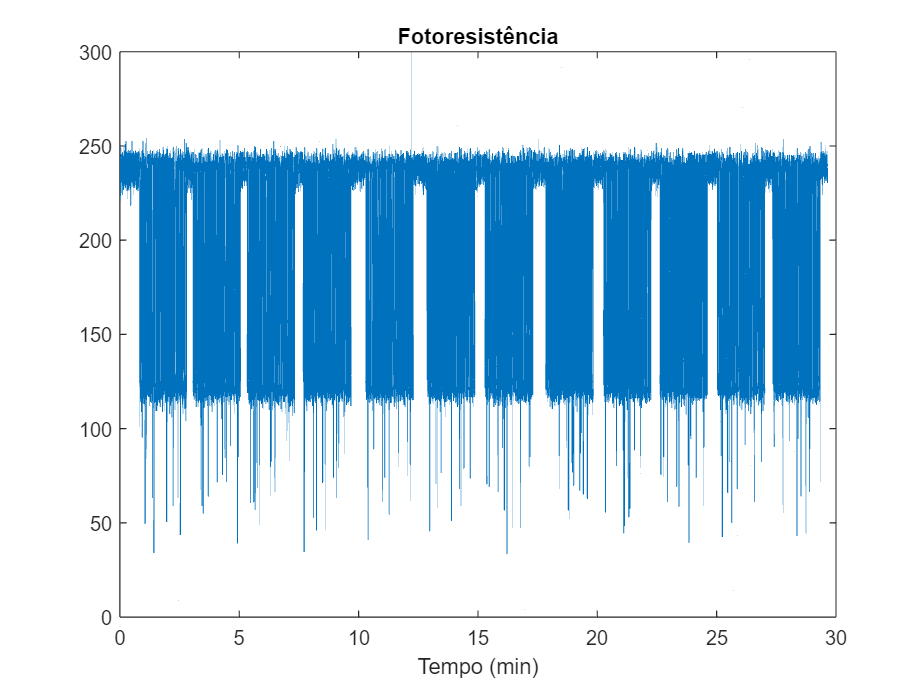

photoVector_seated=(data_seated(:,end));

t_seated = ((0:length(photoVector_seated)-1)*1/fs)/60;
n_pnts = 20;
filt_photoVector_seated = movmedian(photoVector_seated,20);

figure (fig); plot(t_seated,photoVector_seated), title('Fotoresistência'), xlabel('Tempo (min)'); % Sem filtros

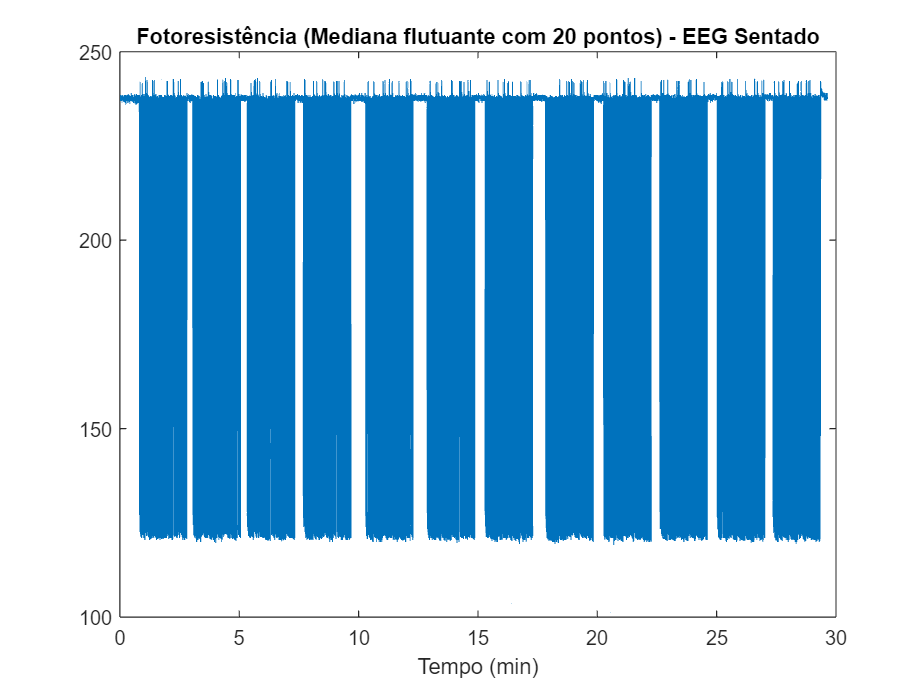

fig = fig + 1;

figure (fig); plot(t_seated,filt_photoVector_seated), title("Fotoresistência (Mediana flutuante com "+n_pnts+" pontos) - EEG Sentado"), xlabel('Tempo (min)');

## Re-referenciação do EEG

eeg_data_seated = data_seated(:,1:end-1);

%car = bsxfun(@minus, eeg_data, mean(eeg_data,2));
%lap = laplacian_perrinX(eeg_data',[nch_locs.X],[nch_locs.Y],[nch_locs.Z]);

## Pré-processamento do EEG

% Filtragem
% De acordo com o artigo com a literatura dos ERPs, um
% filtro passa-banda entre 0.5 e 30/40 Hz será usado.

% Band-pass
bpFilt = designfilt('bandpassfir','FilterOrder',3000, ...
         'CutoffFrequency1',0.1,'CutoffFrequency2',30, ...
         'SampleRate',fs); 
fvtool(bpFilt) % Visualizar resposta em frequência e fase do filtro

%filt_data = filtfilt(bpFilt,car);
%filt_data = filtfilt(bpFilt,lap');

filt_data_seated = filtfilt(bpFilt,eeg_data_seated); % Aplica ZeroPhase

## FFT do sinal

% Verificar se o sinal é um EEG. Para isso, o sinal no domíno das
% frequências tem que seguir a forma 1/f.
% Isto após retirar as componentes DC e dos 50Hz da rede elétrica.

% ----- Sentado -----

T = 1/fs; % Sampling period
L = length(filt_data_seated(:,12)); % Length of signal
tm = (0:L-1)*T; % Time vector
Y = fft(filt_data_seated(:,8)); % Fourier transform
P2 = abs(Y/L); % Two-sided spectrum
P1 = P2(1:floor(L/2)+1); % Single-sided spectrum
P1(2:end-1) = 2*P1(2:end-1);
f = fs*(0:(L/2))/L; % Frequency vector

figure(fig)
fig = fig +1;
plot(f,P1) 
title('Espectro de Amplitudes X(t) - Sentado')
xlabel('f (Hz)')
ylabel('|P1(f)|')

## Retirar sub-harmónica dos 25 Hz

%Band-stop
bsFilt = designfilt('bandstopfir','FilterOrder',3000, ...
         'CutoffFrequency1',24.8,'CutoffFrequency2',25.2, ...
         'SampleRate',fs);
%fvtool(bsFilt)

filt_data_seated = filtfilt(bsFilt,filt_data_seated);

% ICA

%filt_data_seated = pop_loadset()

## Deteção dos índices de segmentação

% ----- Seated -----

last_low = true; 
last_high = false;

falling_edges = [];
rising_edges = [];

for i = 1:length(filt_photoVector_seated)
    photoresistor = filt_photoVector_seated(i);
    if photoresistor <= 235 % Possible falling edge
        if last_high % Found falling edge
            falling_edges = [falling_edges;i];
        end

        last_low = true; 
        last_high = false;

    elseif photoresistor >= 235 % Possible rising edge
        if last_low % Found rising edge
            rising_edges = [rising_edges; i];
        end
        last_low = false;
        last_high = true; 
    end
end

rising_edges(1) = []; 

seg_target_seated = [];
seg_nontarget_seated = [];

for i = 1:length(falling_edges) % Verificar quais blocos pertecem aos targets e não targets
    
    aux = filt_photoVector_seated(falling_edges(i):rising_edges(i));

    if (length(aux)>=60) && (length(aux)<=85)
    
        if(min(aux) < 140)
            seg_nontarget_seated = [seg_nontarget_seated, falling_edges(i)];
        else
            seg_target_seated = [seg_target_seated, falling_edges(i)];
        end

    end

end

seg_target_seated = unique(seg_target_seated);
seg_nontarget_seated = unique(seg_nontarget_seated);

## Segmentação do EEG

bf = -0.200; % 100 ms antes do estímulo
af = 0.800; % 800 ms após o estímulo

idx_bf = floor(bf * fs); % Converter tempo em amostras
idx_af = ceil(af * fs);

time = ((idx_bf:idx_af)/fs) * 1000; % Vetor do tempo em ms

% -------------------
% Target - Sentado

[targetEEG_seated, nontargetEEG_seated] = deal(zeros(length(seg_target_seated), length(time), length(channel_labels))); % Pré-alocação dos dados

for i=1:length(seg_target_seated)
    targetEEG_seated(i,:,:) = cat(3,filt_data_seated((seg_target_seated(i)+idx_bf):(seg_target_seated(i)+idx_af),:));
end

% Non-target - Sentado

for i=1:length(seg_nontarget_seated)
    nontargetEEG_seated(i,:,:) = cat(3,filt_data_seated((seg_nontarget_seated(i)+idx_bf):(seg_nontarget_seated(i)+idx_af),:));
end

## Correção da linha de base

baseline = [-200;0];

baseidx = dsearchn(time',baseline);

% ----- Sentado -----

for t=1:size(targetEEG_seated,1)
    for e=1:size(targetEEG_seated,3)
        tmn = mean(targetEEG_seated(t,baseidx(1):baseidx(2),e));   
        targetEEG_seated(t,:,e) = targetEEG_seated(t,:,e) - tmn;
    end
end 

for t=1:size(nontargetEEG_seated,1)
    for e=1:size(nontargetEEG_seated,3)
        tmn = mean(nontargetEEG_seated(t,baseidx(1):baseidx(2),e));   
        nontargetEEG_seated(t,:,e) = nontargetEEG_seated(t,:,e) - tmn;
    end
end 

## Computação dos ERPs

% ----- Sentado -----

tERP_seated = squeeze(mean(targetEEG_seated, 1)); % ERP target (média do sinal na dimensão trials)
ntERP_seated = squeeze(mean(nontargetEEG_seated, 1)); % ERP não-target

% ----- Sentado c/ som -----

tERP_seatedsound = squeeze(mean(targetEEG_seatedsound, 1)); % ERP target (média do sinal na dimensão trials)

Unrecognized function or variable 'targetEEG_seatedsound'.

ntERP_seatedsound = squeeze(mean(nontargetEEG_seatedsound, 1)); % ERP não-target

## Correção da linha de base dos ERPs 

% nobaseline = tERP_seated;
% 
% baseline = [-200;-100];
% 
% baseidx = dsearchn(time',baseline);
% 
% % ----- Sentado -----
% 
% for e=1:length(channel_labels)
%     tmn = mean(tERP_seated(baseidx(1):baseidx(2),e));   
%     ntmn = mean(ntERP_seated(baseidx(1):baseidx(2),e));   
% 
%     tERP_seated(:,e) = tERP_seated(:,e) - tmn;
%     ntERP_seated(:,e) = ntERP_seated(:,e) - ntmn;
% end

## Baseline vs no baseline

% fig = fig + 1;
% figure(fig)
% hold on,
% xline(0, '--','LineWidth',1.5)
% plot(time,tERP_seated(:,8),'b','LineWidth',2);
% plot(time,nobaseline(:,8),'r','LineWidth',2);
% title("Baseline vs No baseline correction"), xlabel('Time (ms)'), ylabel('Amplitude (\muv)'), grid on
% ph0 = patch([baseline(1) baseline(2) baseline(2) baseline(1)],[12 12 -8 -8],'black');
% set(ph0,'facealpha',.15,'edgecolor','none')
% legend('Stimuli Onset','Baseline corrected','No baseline corrected','Baseline period', 'AutoUpdate', 'off');
% yline(0, ':','LineWidth',1.5)
% hold off,

## Single trial plot

fig = fig + 1;
figure(fig)
hold on, grid on,
xline(0, '--','LineWidth',1.5)
yline(0, ':','LineWidth',1.5)
title(nch_locs(8).labels)
plot(time,targetEEG_fmri(101,:,8),'b','LineWidth',2);

## Tempos dos picos

% Definição do tempo dos picos e respetivos índices 

tN170 = [90; 130]; % ms
idxN170 = dsearchn(time',tN170);

tN2 = [180; 230];
idxN2 = dsearchn(time',tN2);

tP3 = [240; 340];
idxP3 = dsearchn(time',tP3);

## Comparação dos ERPs entre condições - Target

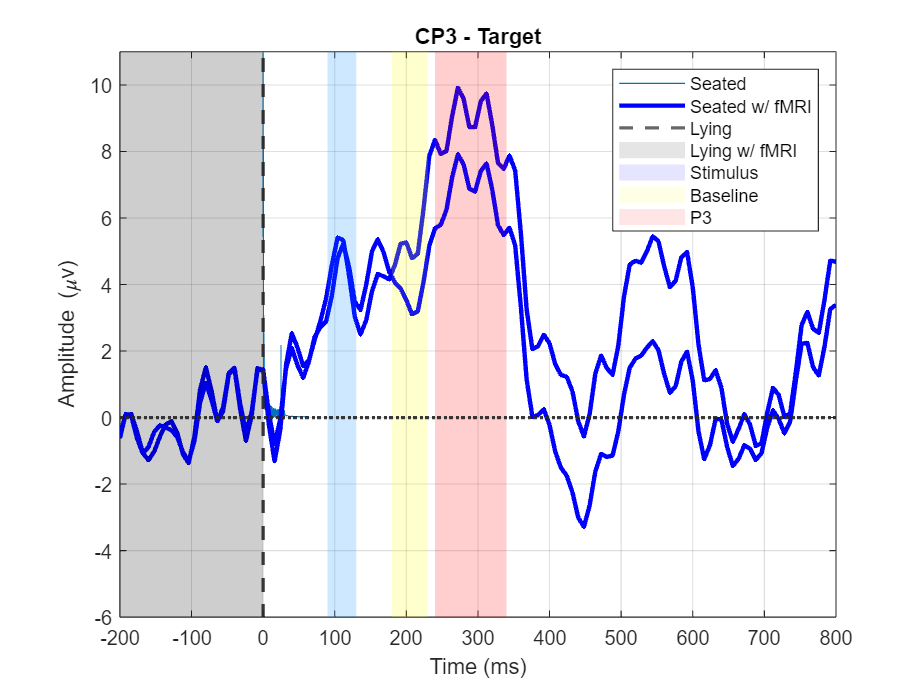

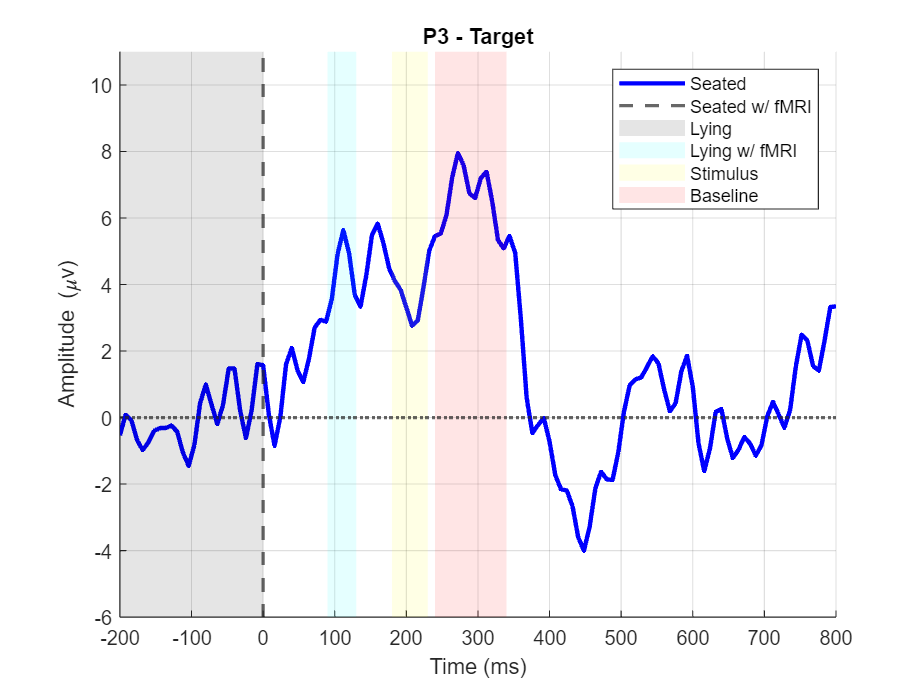

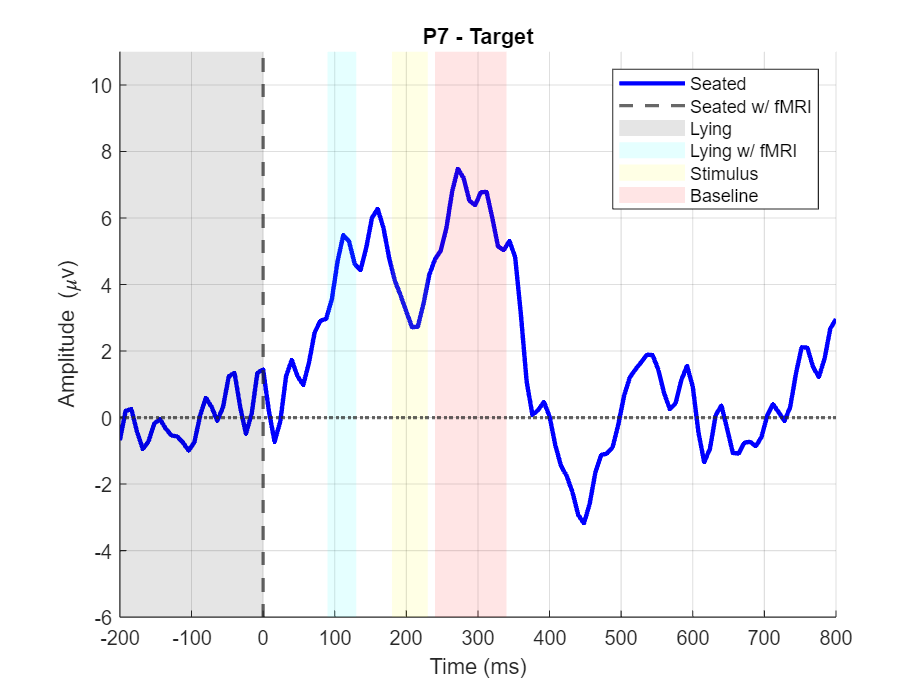

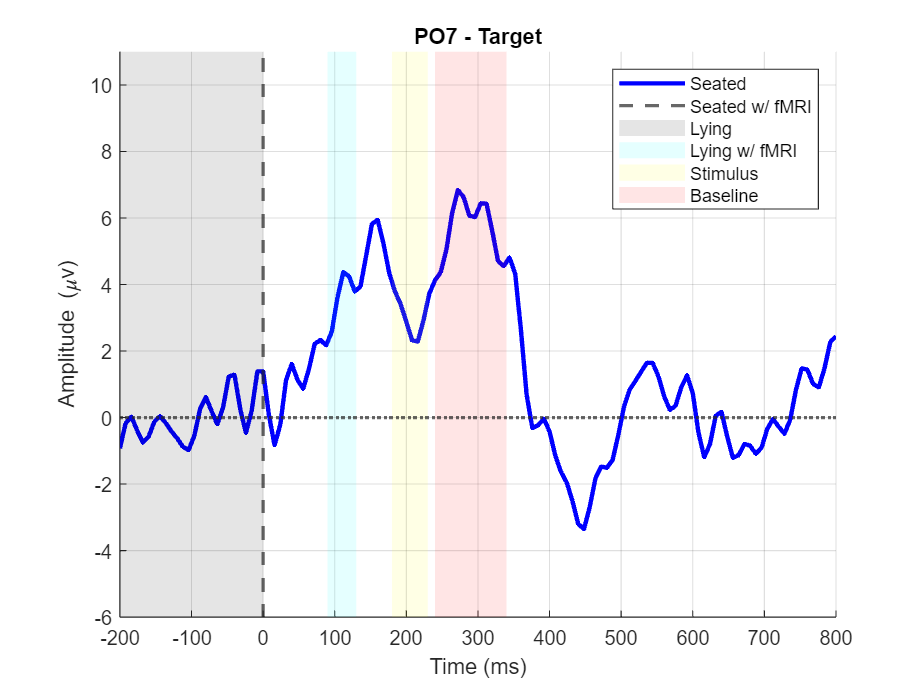

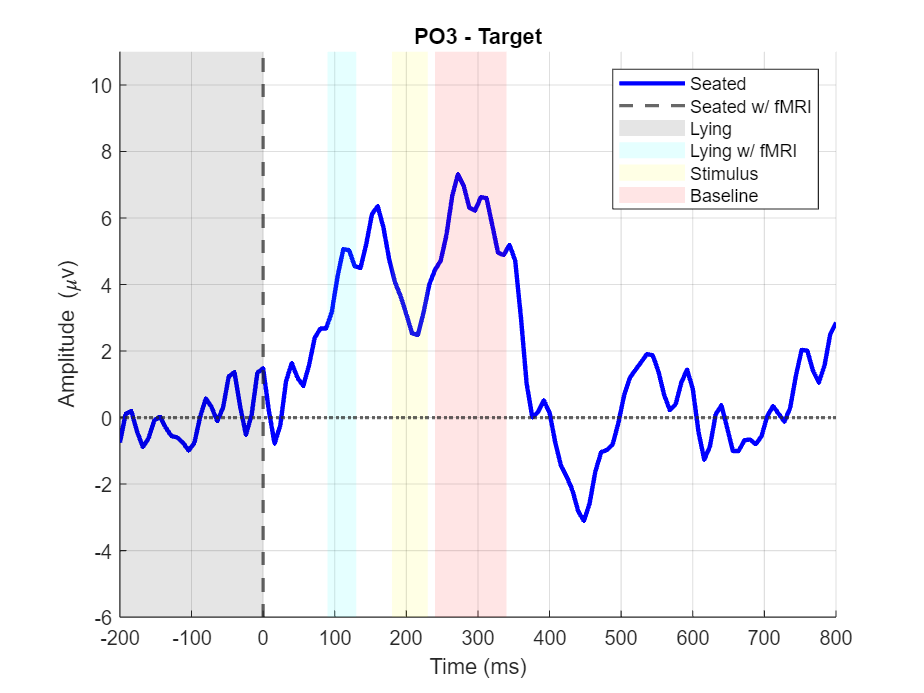

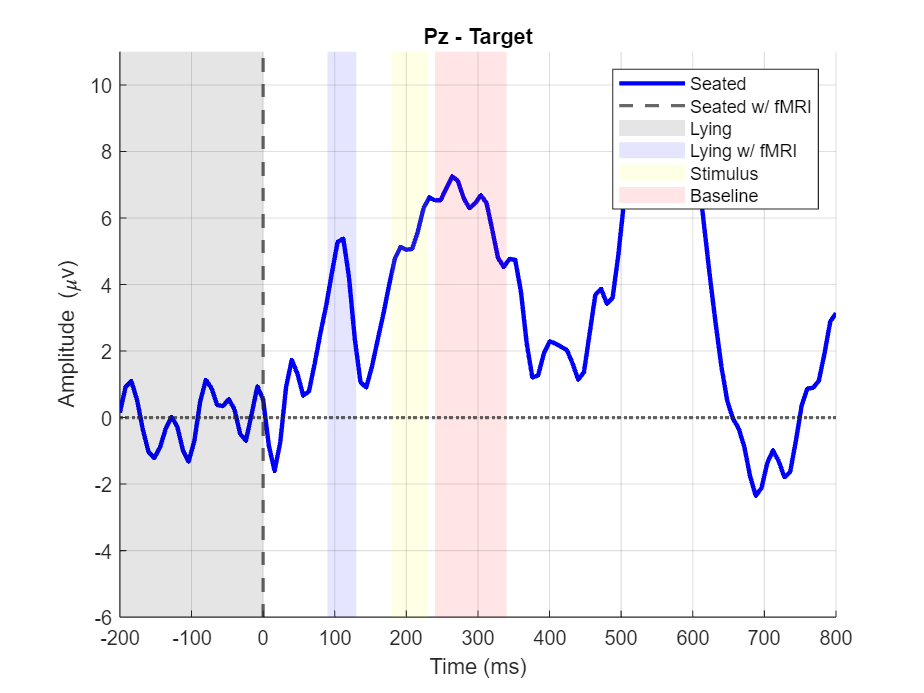

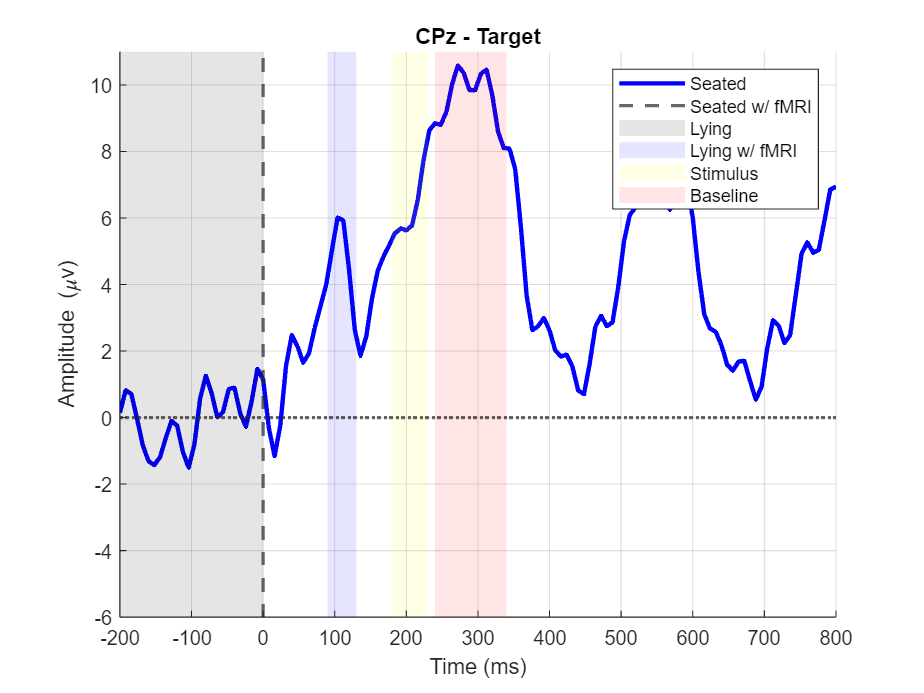

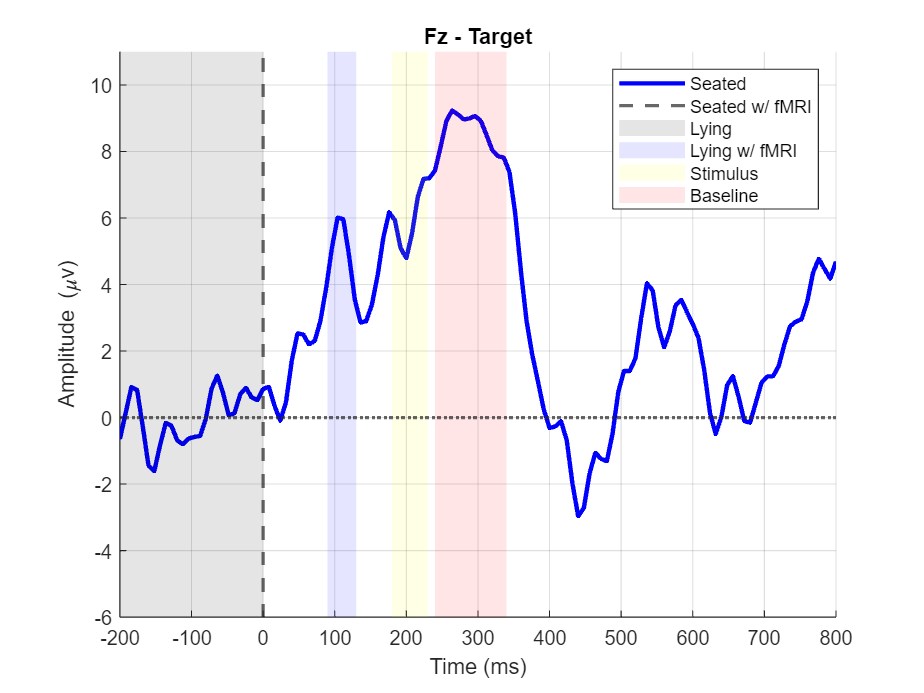

% Gráficos dos ERPs no tempo

clim = [floor(min(min(tERP_seated))),ceil(max(max(tERP_seated))),];

clim = [min(min(clim)),max(max(clim))];

aux = 0;

for i=1:length(channel_labels)
    figure(fig)
    hold on,
    fig = fig + 1;
    plot(time,tERP_seated(:,i),'b','LineWidth',2);
    xline(0, '--','LineWidth',1.5)    
    ylim([(clim(1)+aux),(clim(2)-aux)])
    xlim([min(time),max(time)])
    title(channel_labels(i) + " - Target"), xlabel('Time (ms)'), ylabel('Amplitude (\muv)'), grid on
    
    if(contains(channel_labels(i),"z") || (contains(channel_labels(i),"C") && ~(contains(channel_labels(i),"P"))) ) % VPP
        c = 'blue';
        a = 'VPP';
        N2 = [tN2(1), tN2(2), tN2(2), tN2(1)];
    else % N170
        c = 'cyan';
        a = 'N170';
        N2 = [tN2(1), tN2(2), tN2(2), tN2(1)];
    end
   
    N170 = [tN170(1), tN170(2), tN170(2), tN170(1)];
    P3 = [tP3(1), tP3(2), tP3(2), tP3(1)];

    % Estas patches precisam de ser ajustadas

    ph0 = patch([baseline(1) baseline(2) baseline(2) baseline(1)],[clim(1) clim(1) clim(2) clim(2)],'black');
    set(ph0,'facealpha',.1,'edgecolor','none')

    ph1 = patch(N170,[clim(1) clim(1) clim(2) clim(2)],c);
    set(ph1,'facealpha',.1,'edgecolor','none')

    ph2 = patch(N2,[clim(1) clim(1) clim(2) clim(2)],'y');
    set(ph2,'facealpha',.1,'edgecolor','none')
    
    ph3 = patch(P3,[clim(1) clim(1) clim(2) clim(2)],'r');
    set(ph3,'facealpha',.1,'edgecolor','none')

    legend('Seated','Seated w/ fMRI', 'Lying', 'Lying w/ fMRI','Stimulus','Baseline', 'P3','AutoUpdate', 'off')
    
    yline(0, ':','LineWidth',1.5)
    hold off
    
end

## Mapas topográficos - Target

figure(fig)
fig = fig + 1;
tlo1=tiledlayout(1,3,'TileSpacing','none','Padding','none');
title(tlo1, ["Target";""], 'FontSize', 15, 'FontWeight','Bold');

n_cont = 10;

ax1=nexttile(tlo1);
topoplot(mean(tERP_seated(idxN170(1):idxN170(2),:)),nch_locs,'maplimits',clim,'numcontour',n_cont,'electrodes','on');

title(ax1,"N170 - VPP (" + tN170(1) +" - "+ tN170(2) + " ms)"  ,'FontSize',12)

ax2=nexttile(tlo1);
topoplot(mean(tERP_seated(idxN2(1):idxN2(2),:)),nch_locs,'maplimits',clim,'numcontour',n_cont,'electrodes','on');

title(ax2,"N2 (" + tN2(1) +" - "+ tN2(2) + " ms)",'FontSize',12)

ax3=nexttile(tlo1);
topoplot(mean(tERP_seated(idxP3(1):idxP3(2),:)),nch_locs,'maplimits',clim,'numcontour',n_cont,'electrodes','on');

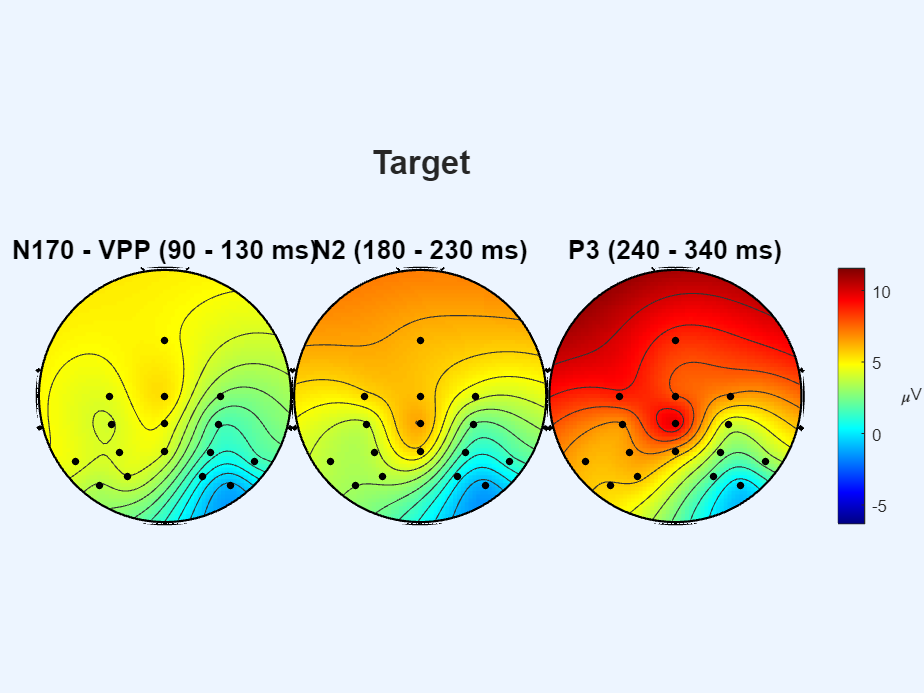

title(ax3,"P3 (" + tP3(1) +" - "+ tP3(2) + " ms)",'FontSize',12)

cbh2=colorbar(ax1);
cbh2.Layout.Tile = 'east';
cbh2.Label.String='\muV';
chh2.Label.FontSize = 16;
cbh2.Label.Rotation=0;

## Comparação entre condições - Non-Target

% Gráficos dos ERPs no tempo

aux = 0;

for i=1:length(channel_labels)
    figure(fig)
    hold on,
    fig = fig + 1;
    plot(time,ntERP_seated(:,i),'b','LineWidth',2);
    plot(time,ntERP_lying(:,i),'r','LineWidth',2);
    plot(time,ntERP_fmri(:,i),'g','LineWidth',2);
    xline(0, '--')    
    ylim([(clim(1)+aux),(clim(2)-aux)])
    xlim([min(time),max(time)])
    title(channel_labels(i) + " - Non-Target"), xlabel('Tempo (ms)'), ylabel('Amplitude (\muv)'), grid on
    
    if(contains(channel_labels(i),"z") || (contains(channel_labels(i),"C") && ~(contains(channel_labels(i),"P"))) ) % VPP
        c = 'blue';
        a = 'VPP';
        N2 = [tN2(1), tN2(2), tN2(2), tN2(1)];
    else % N170
        c = 'cyan';
        a = 'N170';
        N2 = [tN2(1), tN2(2), tN2(2), tN2(1)];
    end
   
    N170 = [tN170(1), tN170(2), tN170(2), tN170(1)];
    P3 = [tP3(1), tP3(2), tP3(2), tP3(1)];

    % Estas patches precisam de ser ajustadas

    ph0 = patch([baseline(1) baseline(2) baseline(2) baseline(1)],[clim(1) clim(1) clim(2) clim(2)],'black');
    set(ph0,'facealpha',.1,'edgecolor','none')

    ph1 = patch(N170,[clim(1) clim(1) clim(2) clim(2)],c);
    set(ph1,'facealpha',.1,'edgecolor','none')

    ph2 = patch(N2,[clim(1) clim(1) clim(2) clim(2)],'y');
    set(ph2,'facealpha',.1,'edgecolor','none')
    
    ph3 = patch(P3,[clim(1) clim(1) clim(2) clim(2)],'r');
    set(ph3,'facealpha',.1,'edgecolor','none')

    legend('EEG Seated','EEG Lying','EEG w/ fMRI','Stimulus','Baseline',a, 'N2', 'P3','AutoUpdate', 'off')
    
    yline(0, ':')
    hold off
    
end

## Mapas topográficos - Non-target

clim = [floor(min(min(tERP_seated))),ceil(max(max(tERP_seated))),
        floor(min(min(tERP_fmri))),ceil(max(max(tERP_fmri))),
        floor(min(min(tERP_lying))),ceil(max(max(tERP_lying)))];

clim = [min(min(clim)),max(max(clim))];

figure(fig)
fig = fig + 1;
tlo1=tiledlayout(3,3,'TileSpacing','tight','Padding','tight');
title(tlo1, ["NonTarget | EEG seated (Top) | EEG Lying (Middle) | EEG w/ fMRI (Low) ";""], 'FontSize', 15, 'FontWeight','Bold');

ax1=nexttile(tlo1);
topoplot(mean(ntERP_seated(idxN170(1):idxN170(2),:)),nch_locs,'maplimits',clim,'numcontour',n_cont,'electrodes','on');
title(ax1,"N170 - VPP (" + tN170(1) +" - "+ tN170(2) + " ms)"  ,'FontSize',12)

ax2=nexttile(tlo1);
topoplot(mean(ntERP_seated(idxN2(1):idxN2(2),:)),nch_locs,'maplimits',clim,'numcontour',n_cont,'electrodes','on');
title(ax2,"N2 (" + tN2(1) +" - "+ tN2(2) + " ms)",'FontSize',12)

ax3=nexttile(tlo1);
topoplot(mean(ntERP_seated(idxP3(1):idxP3(2),:)),nch_locs,'maplimits',clim,'numcontour',n_cont,'electrodes','on');
title(ax3,"P3 (" + tP3(1) +" - "+ tP3(2) + " ms)",'FontSize',12)

ax4=nexttile(tlo1);
topoplot(mean(ntERP_lying(idxN170(1):idxN170(2),:)),nch_locs,'maplimits',clim,'numcontour',n_cont,'electrodes','on');

ax5=nexttile(tlo1);
topoplot(mean(ntERP_lying(idxN2(1):idxN2(2),:)),nch_locs,'maplimits',clim,'numcontour',n_cont,'electrodes','on');

ax6=nexttile(tlo1);
topoplot(mean(ntERP_lying(idxP3(1):idxP3(2),:)),nch_locs,'maplimits',clim,'numcontour',n_cont,'electrodes','on');

ax7=nexttile(tlo1);
topoplot(mean(ntERP_fmri(idxN170(1):idxN170(2),:)),nch_locs,'maplimits',clim,'numcontour',n_cont,'electrodes','on');

ax8=nexttile(tlo1);
topoplot(mean(ntERP_fmri(idxN2(1):idxN2(2),:)),nch_locs,'maplimits',clim,'numcontour',n_cont,'electrodes','on');

ax9=nexttile(tlo1);
topoplot(mean(ntERP_fmri(idxP3(1):idxP3(2),:)),nch_locs,'maplimits',clim,'numcontour',n_cont,'electrodes','on');

cbh2=colorbar(ax9);
cbh2.Layout.Tile = 'east';
cbh2.Label.String='\muV';
chh2.Label.FontSize = 16;
cbh2.Label.Rotation=0;

## Comparação entre condições (EEG Movies) - Target vs Non-Target

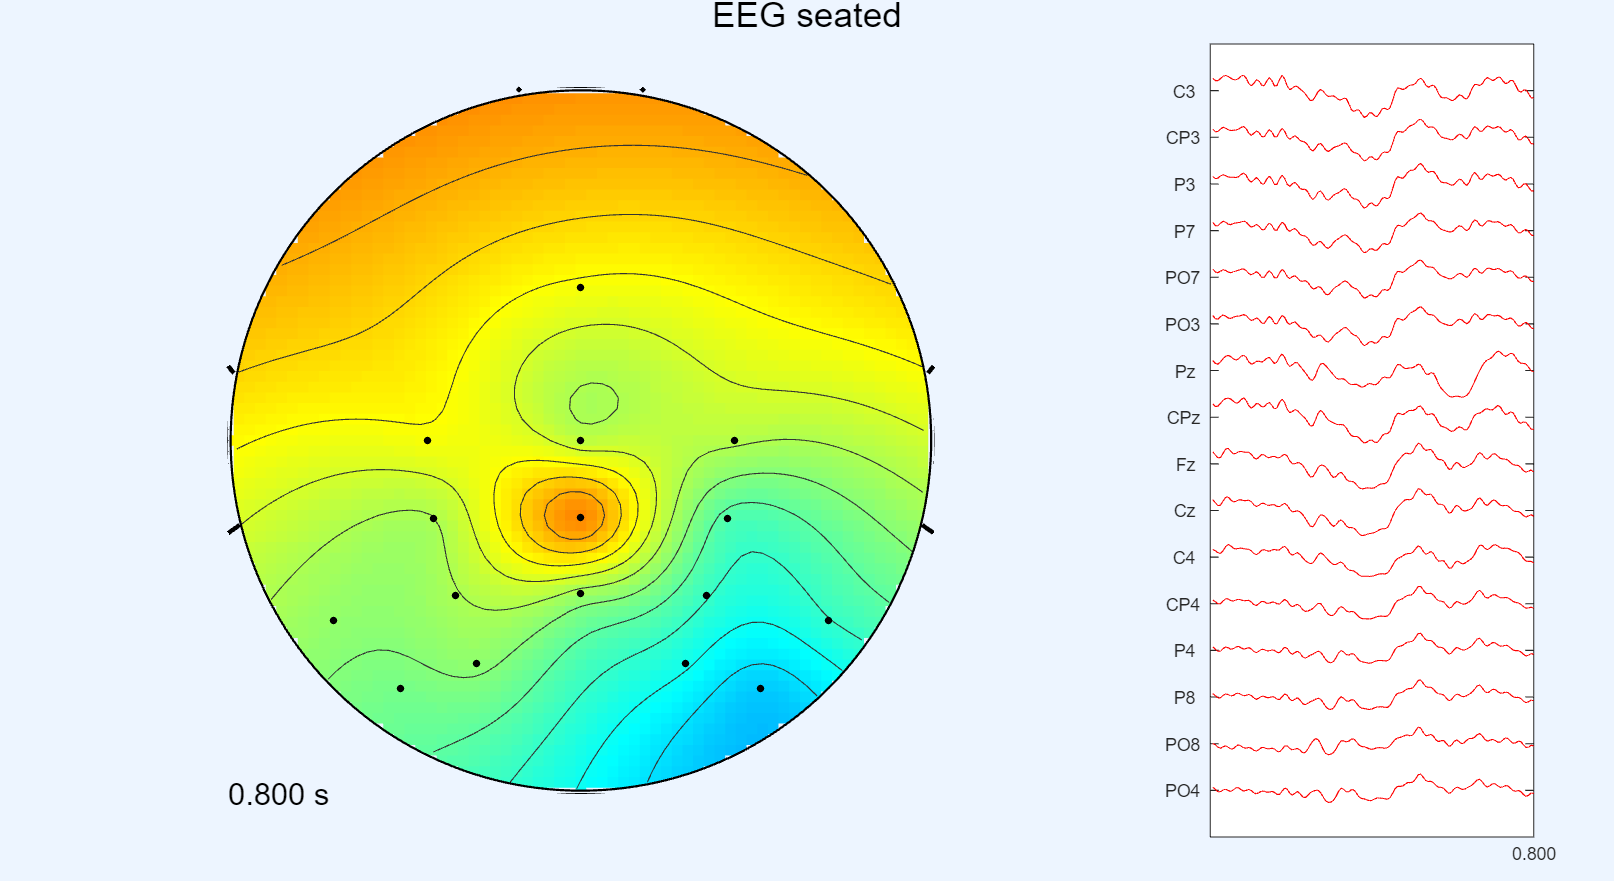

Making a movie of 126 frames
   ...

   ..........10..........20..........30..........40..........50
..........60..........70..........80..........90..........100
..........110..........120.....

.
Done


%% 2D movie of topographic ERPs (Target - Seated)

figure('units','pixels','position',[0 0 1920 1080]); 
set(gcf, 'WindowState', 'maximized');

targ_seated = eegmovie(tERP_seated', fs, nch_locs ,...
     'time','on','startsec',-0.200 , 'topoplotopt', ...
     {'numcontour' n_cont},'minmax',clim,'title','EEG seated');


seemovie(targ_seated,0,clim);

Movie will play slowly once, then 10 times faster forwards and backwards.
   Close figure to abort:  


%% 2D movie of topographic ERPs (NonTarget - Seated)

% figure('units','pixels','position',[0 0 1920 1080]); 
% set(gcf, 'WindowState', 'maximized');
% 
% nontarg_seated = eegmovie(ntERP_seated', fs, nch_locs ,...
%      'time','on','startsec',-0.200 , 'topoplotopt', ...
%      {'numcontour' n_cont},'minmax',clim,'title','EEG seated');
% 
% seemovie(nontarg_seated,0,clim);
